# Controller Project

## Authors:

### Mohammad Mahdi Mohebbati - 97107075

### Alireza Miryazdi - 97107201

## The Problem

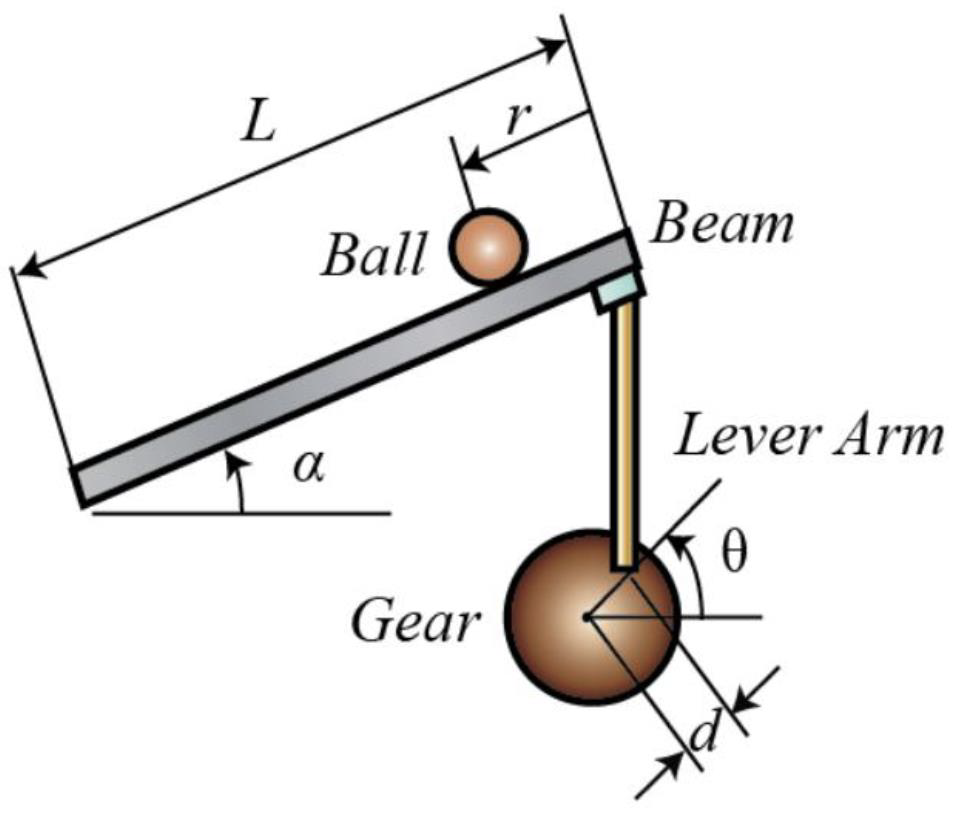

In above schematic, the ball is required to be positioned at exactly the center of the beam, and a controller is to be designed that meets specific requirements of the system. 

The constant system properties are as follows:

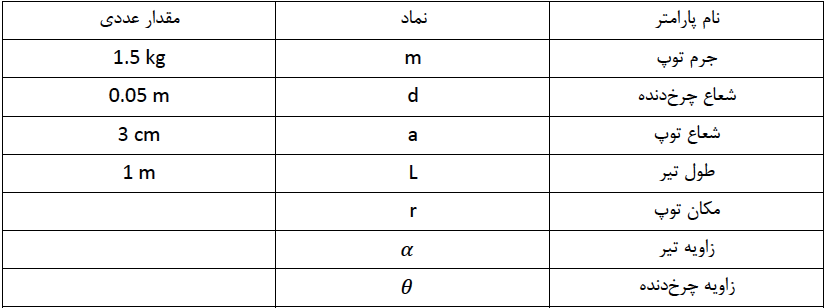

The transfer function of the system can be described as the following:  


$$\frac{R}{\theta} = \frac{m g sin\alpha}{(\frac{J}{a^2}+m)s^2} \\ sin\alpha = \frac{d}{l} sin\theta$$


Using a first order approximation of the system yields:


$$\frac{R}{\theta} = \frac{m g d}{\frac{7}{5}L s^2} = \frac{0.735}{1.4 s^2}$$


The motor and gearbox are approximated to have the following transfer function:


$$\frac{\theta}{V} = \frac{0.0274}{0.003228s^2+0.003508s}$$


The following relationship also appears:


$$R = 2 V$$


Written in MATLAB we have:

clc
close all
clear
s = tf('s');
tf_motor = tf([0.0274], [0.003228 0.003508 0]);
tf_gearbox = tf([1/5], [1]);
tf_approx_model = tf([0.735], [1.4 0 0]);
tf_voltage = tf([1/2], [1]);

## Stabilizing and Designing a PID Using SISOTOOL

The first part requires that we design a PID controller using the SISO tool provided by MATLAB. The system has Before we do that though, we might need to design a system stabilizer since a PID alone might not guarantee stability.

First we create the system model in MATLAB. This model is based on the approximated model suggested in the problem:

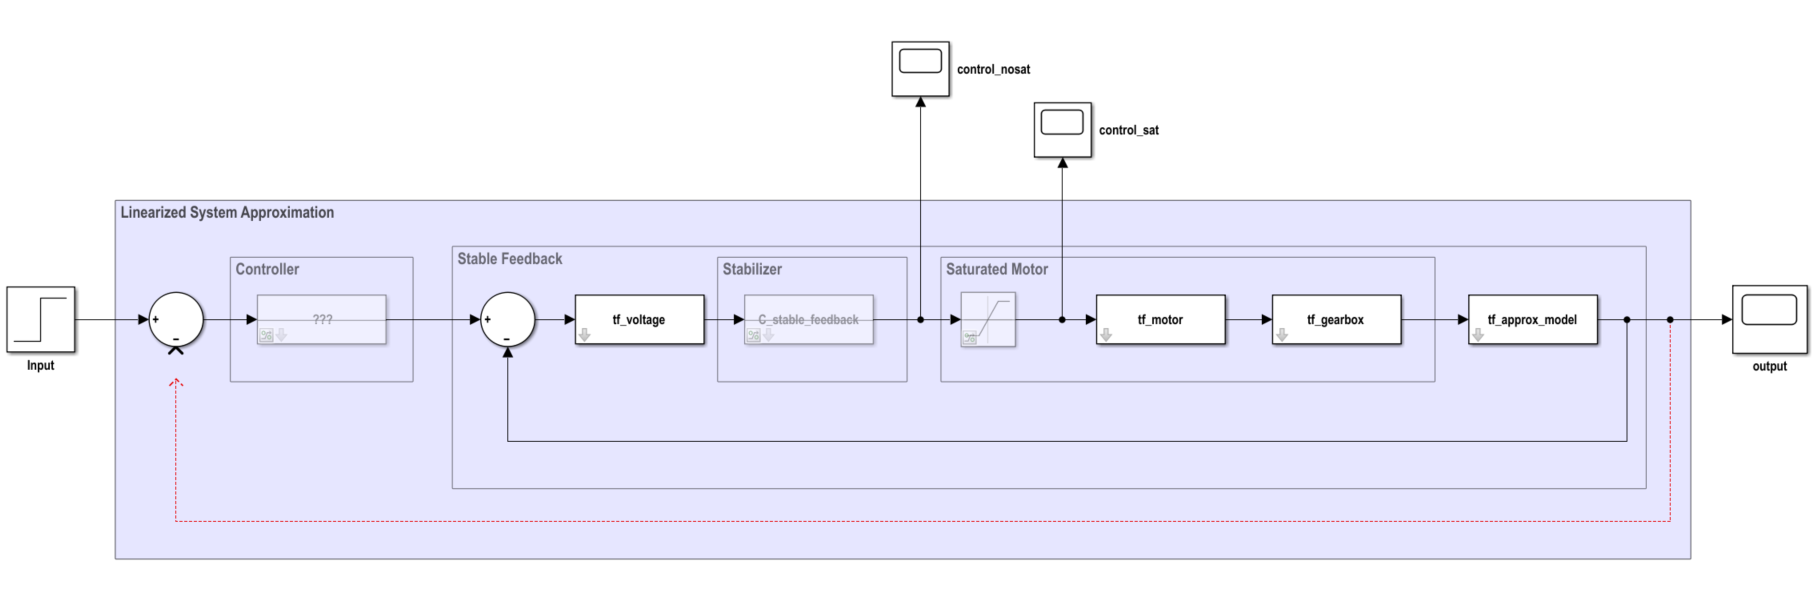

We can see the model consists of a controller (required to be PID) and a stabilizer. The model also includes a saturation element for the motor,  though this is commented at the moment and will have to be enabled in the final results. This initial model can be viewed in the `model_base.slx` file.

The system has 3 poles! This makes it impossible to fully stabilize the system using just one PID. therefore, we need to design a stabilizer for the system.To do this, the transfer function of our plant is the series of our motor, gearbox and approximate model. This can be seen in the block labeled `Stable Feedback` in the model.

G_stable_feedback = tf_motor * tf_gearbox * tf_approx_model * tf_voltage;

To design the stabilizer in SISO tool, we first create the model in it. The architecture of the stable feedback is as follows:

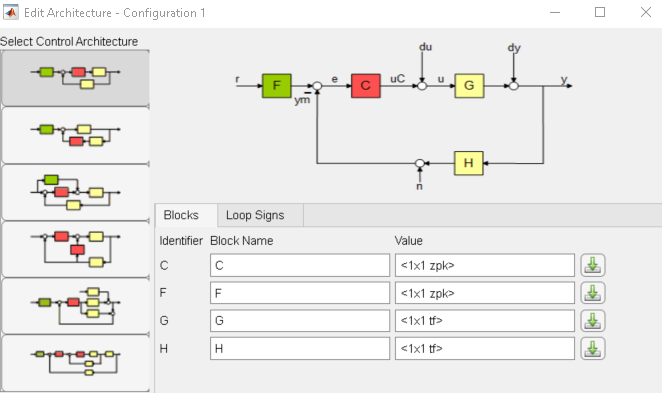

In the above plant, the value of `G_stable_feedback` is imported. The resulting closed-loop system is predictably unstable:

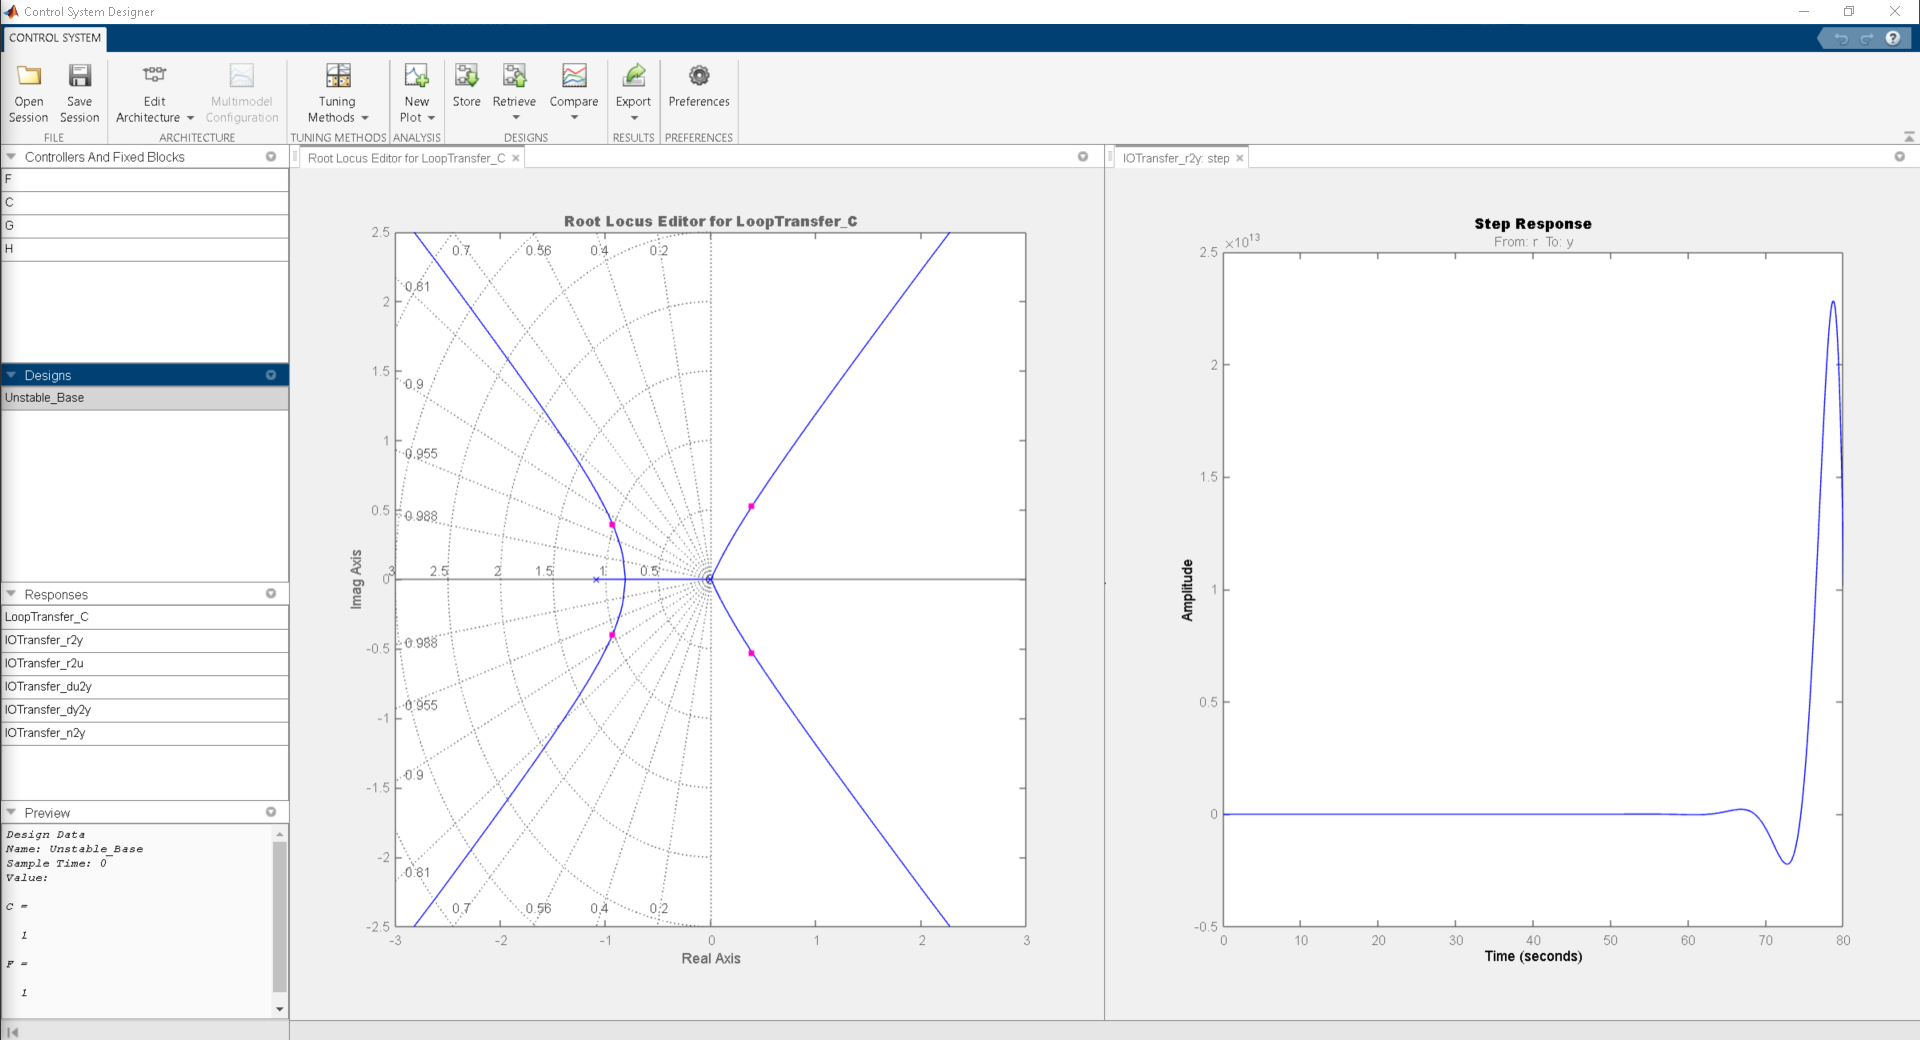

To stabilize the system, we have tried using many different method as commented in the SISO design list. However, using 4 leads seems to have desirable results. It stabilizes the system are removes steady-state error:

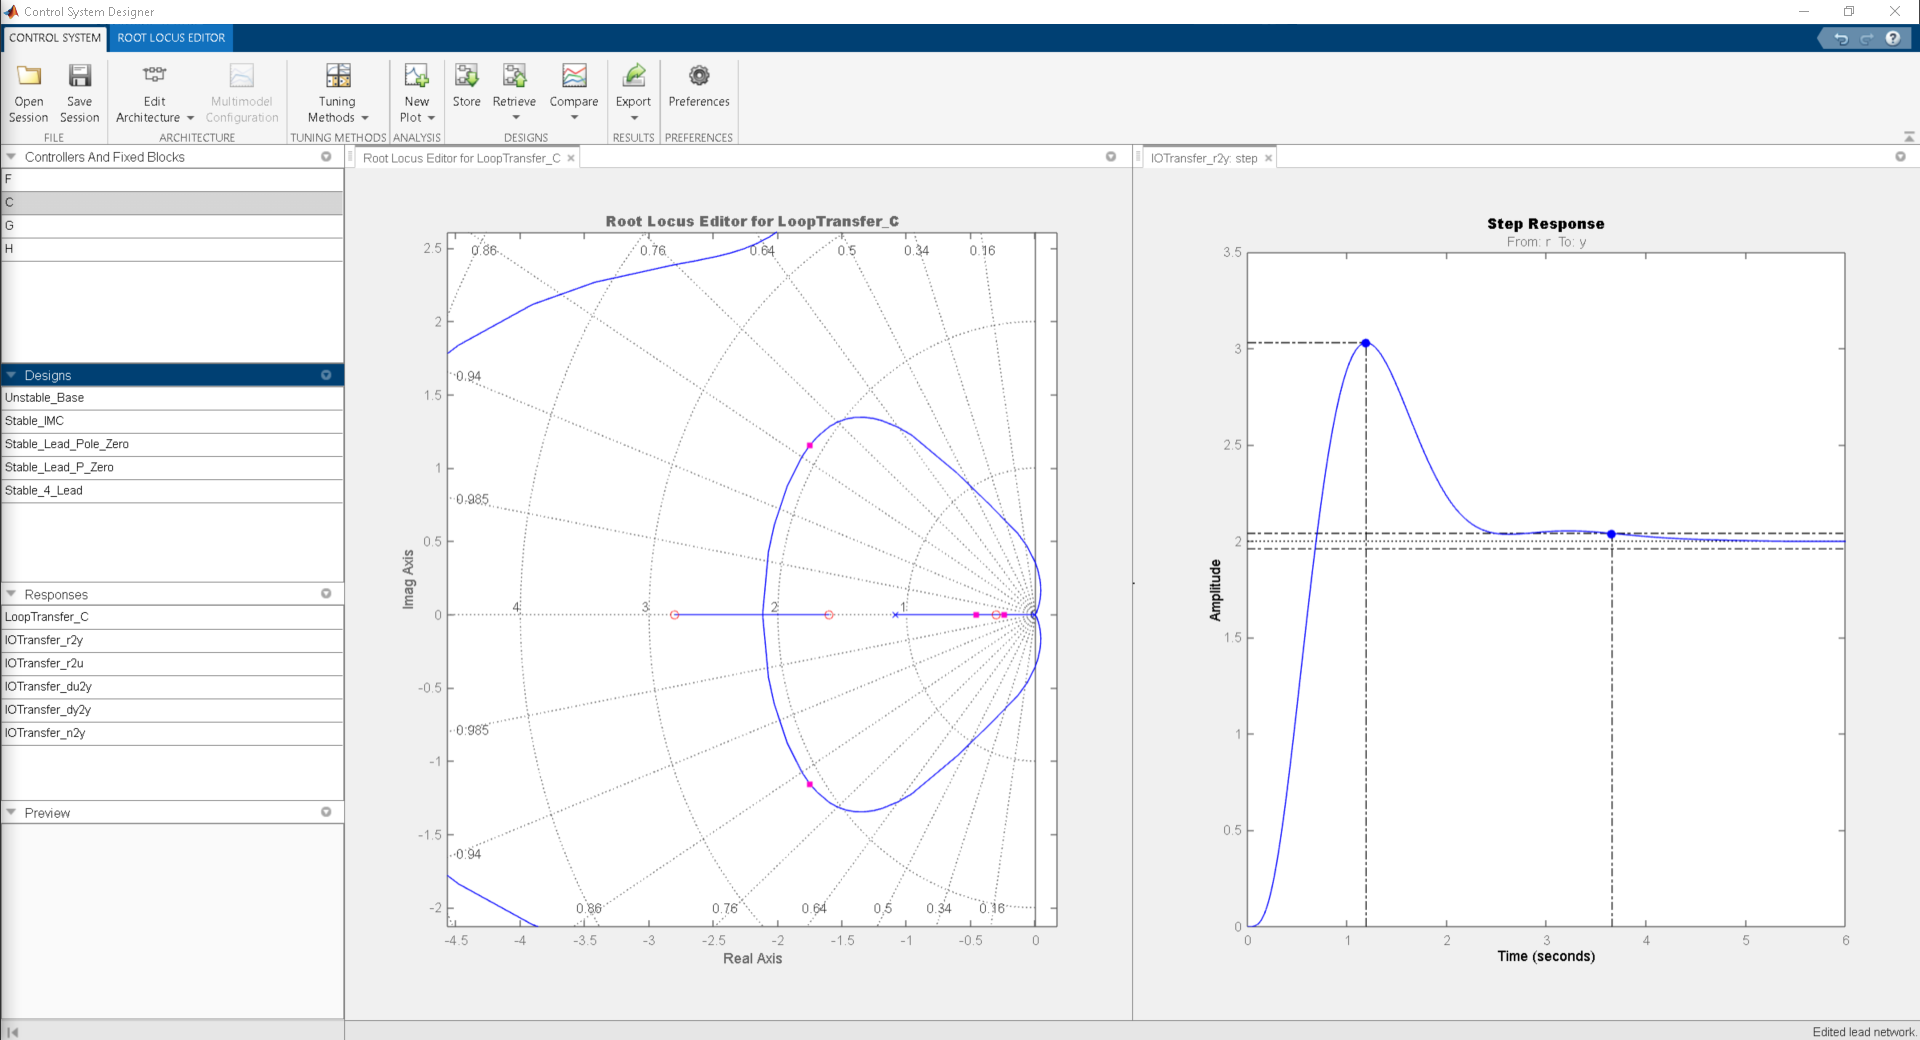

The system provides a settling time of 3.66s and overshoot of 51.5%, which can be corrected using the to be designed PID controller. The values of our stabilizer can be imported from the `stabilizer.mat` file:

load stabilizer.mat
[~,~,~,~,temp] = ControlSystemDesignerSession.DesignerData.Designs.Data;
C_stable_feedback = temp.C;
clear temp

With our new stabilizer, the model can be updated. The `model_stabilizer_only.slx` file showcases the approximate model with no saturation that implements this stabilizer. Running the model yields these results:

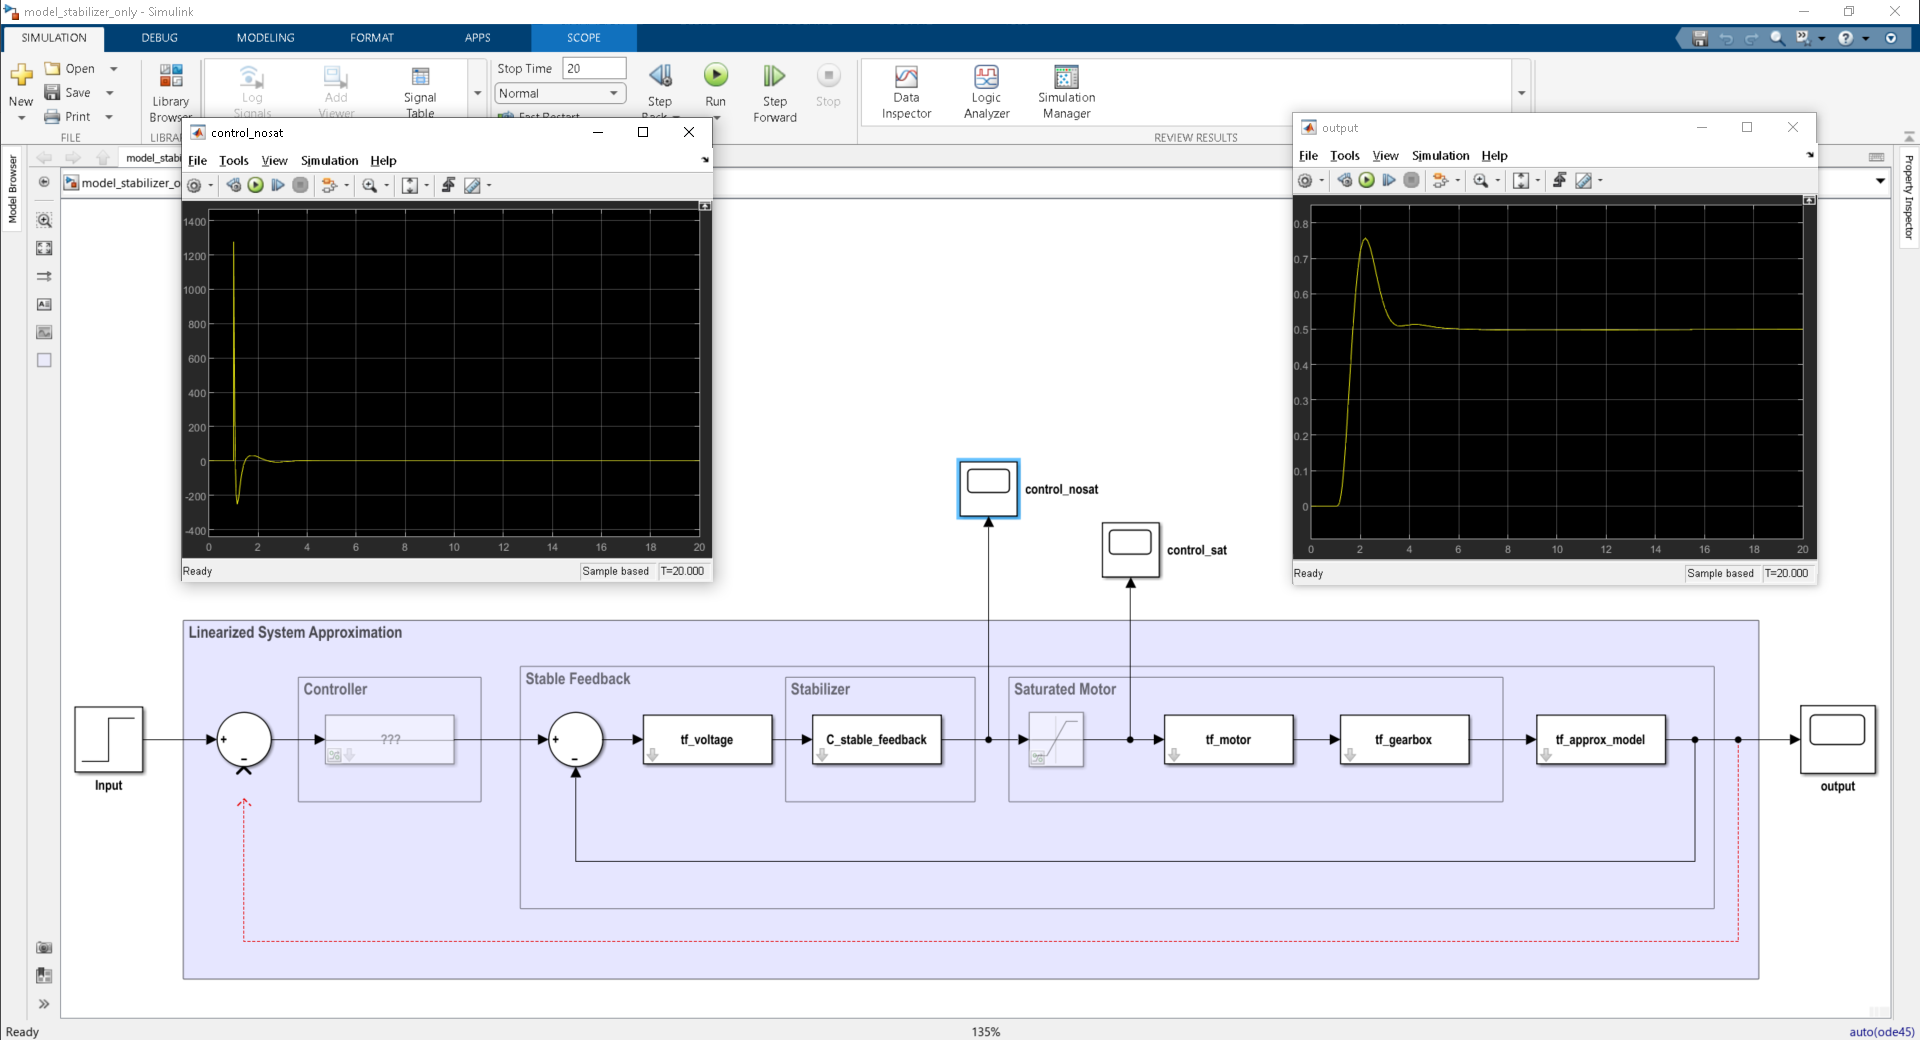

The system is stable; however, the controller signal jumps up to 1300 at one point! This will likely cause problems when saturation is added. So we keep this in mind when designing the PID.

Now to design the PID itself. We first create the architecture that will be used in SISO tool:

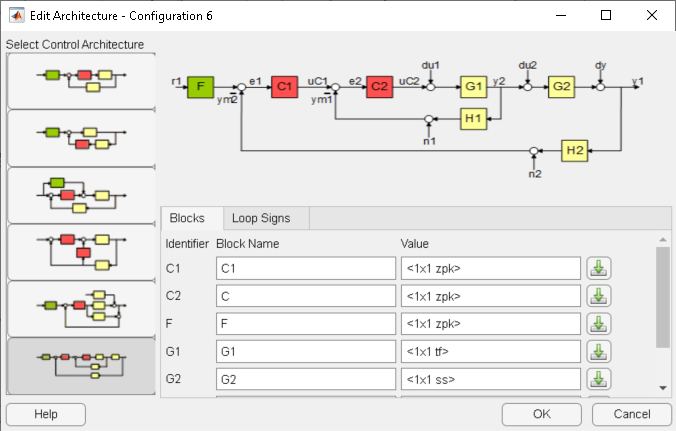

Where `G1 = G_stable_feedback`, `G2 = 1`, `C2 = C_stable_feedback` and `H1=H2=1`. Here, `C1` is the PID to be designed. The closed-loop system is already stable:

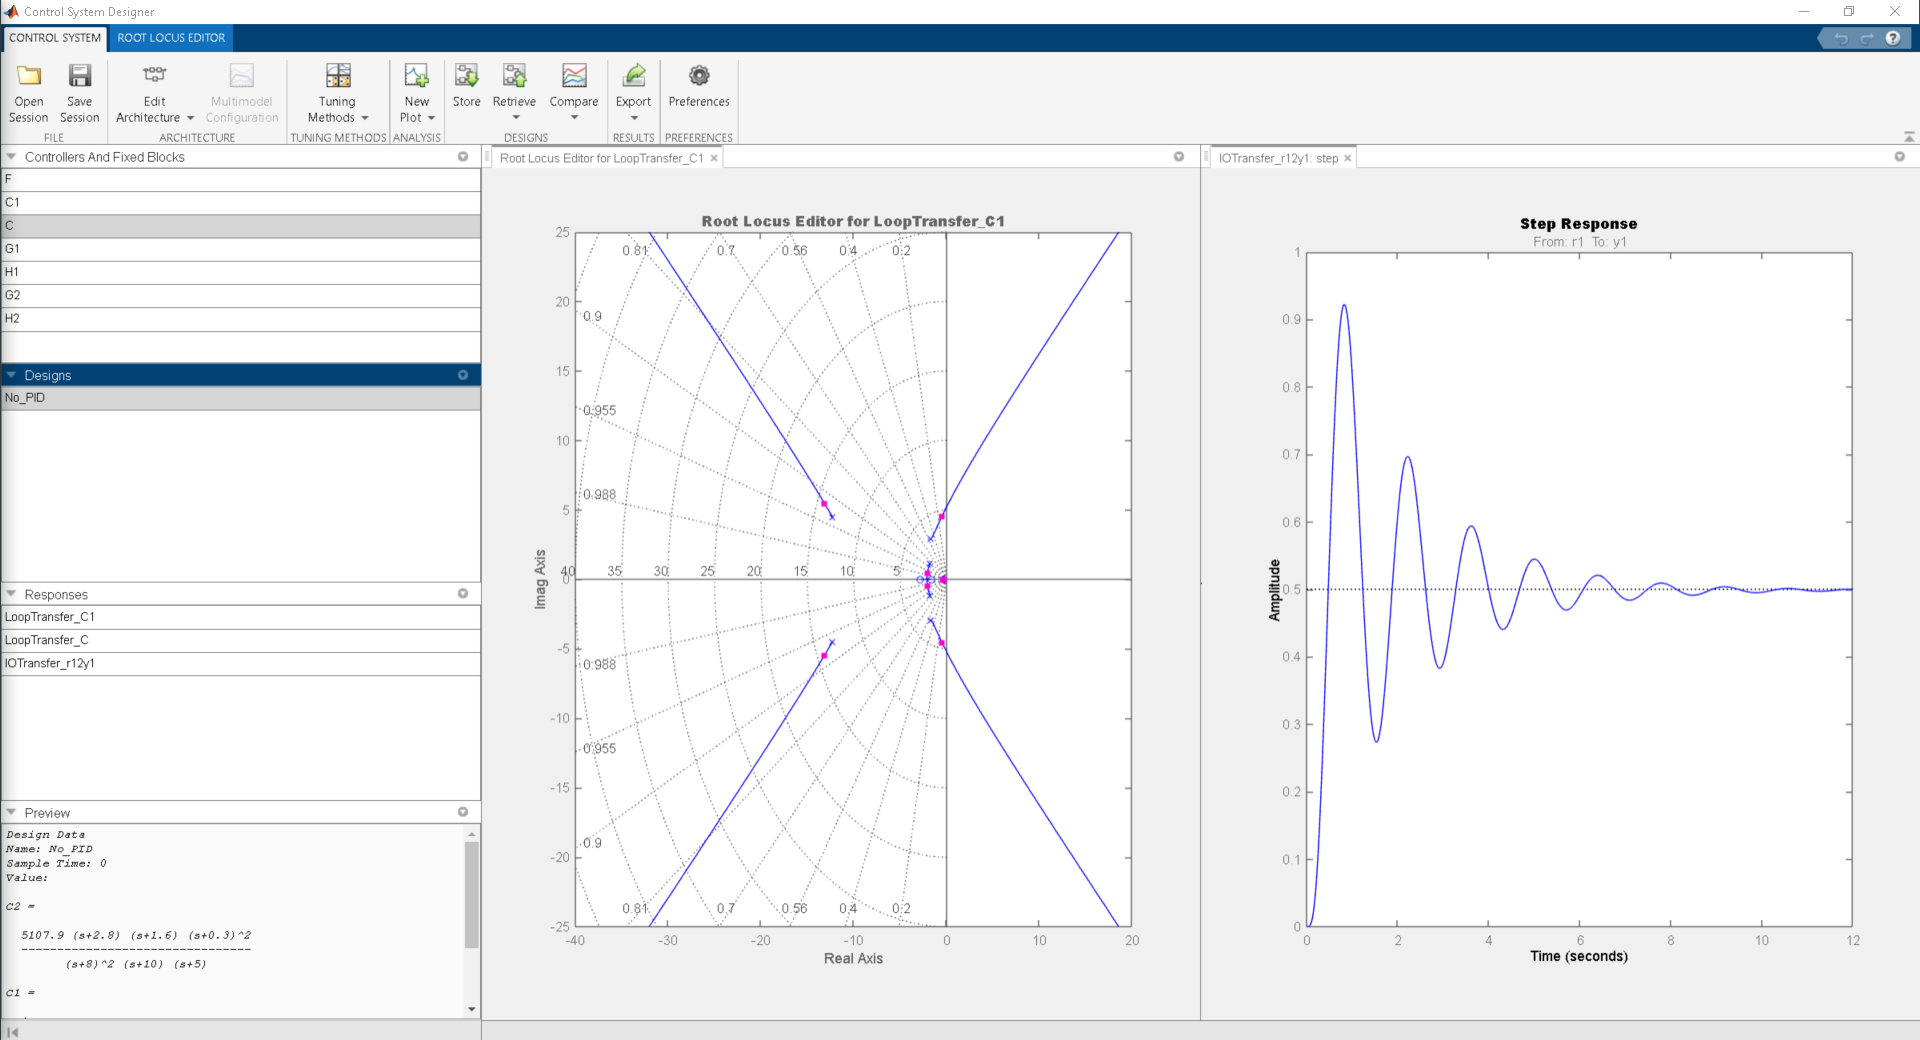

However, it can be drastically improved by using a PID controller. The PID Tuning tool is used to do this and achieve the desired maximum peak response of **20 percent **and settling time of  **8 seconds**. Note that a first order derivative filter also needs to be used so the PID controller itself is feasable. To make sure saturation is minimal, the `r1 -> uC2` step response is also plotted.

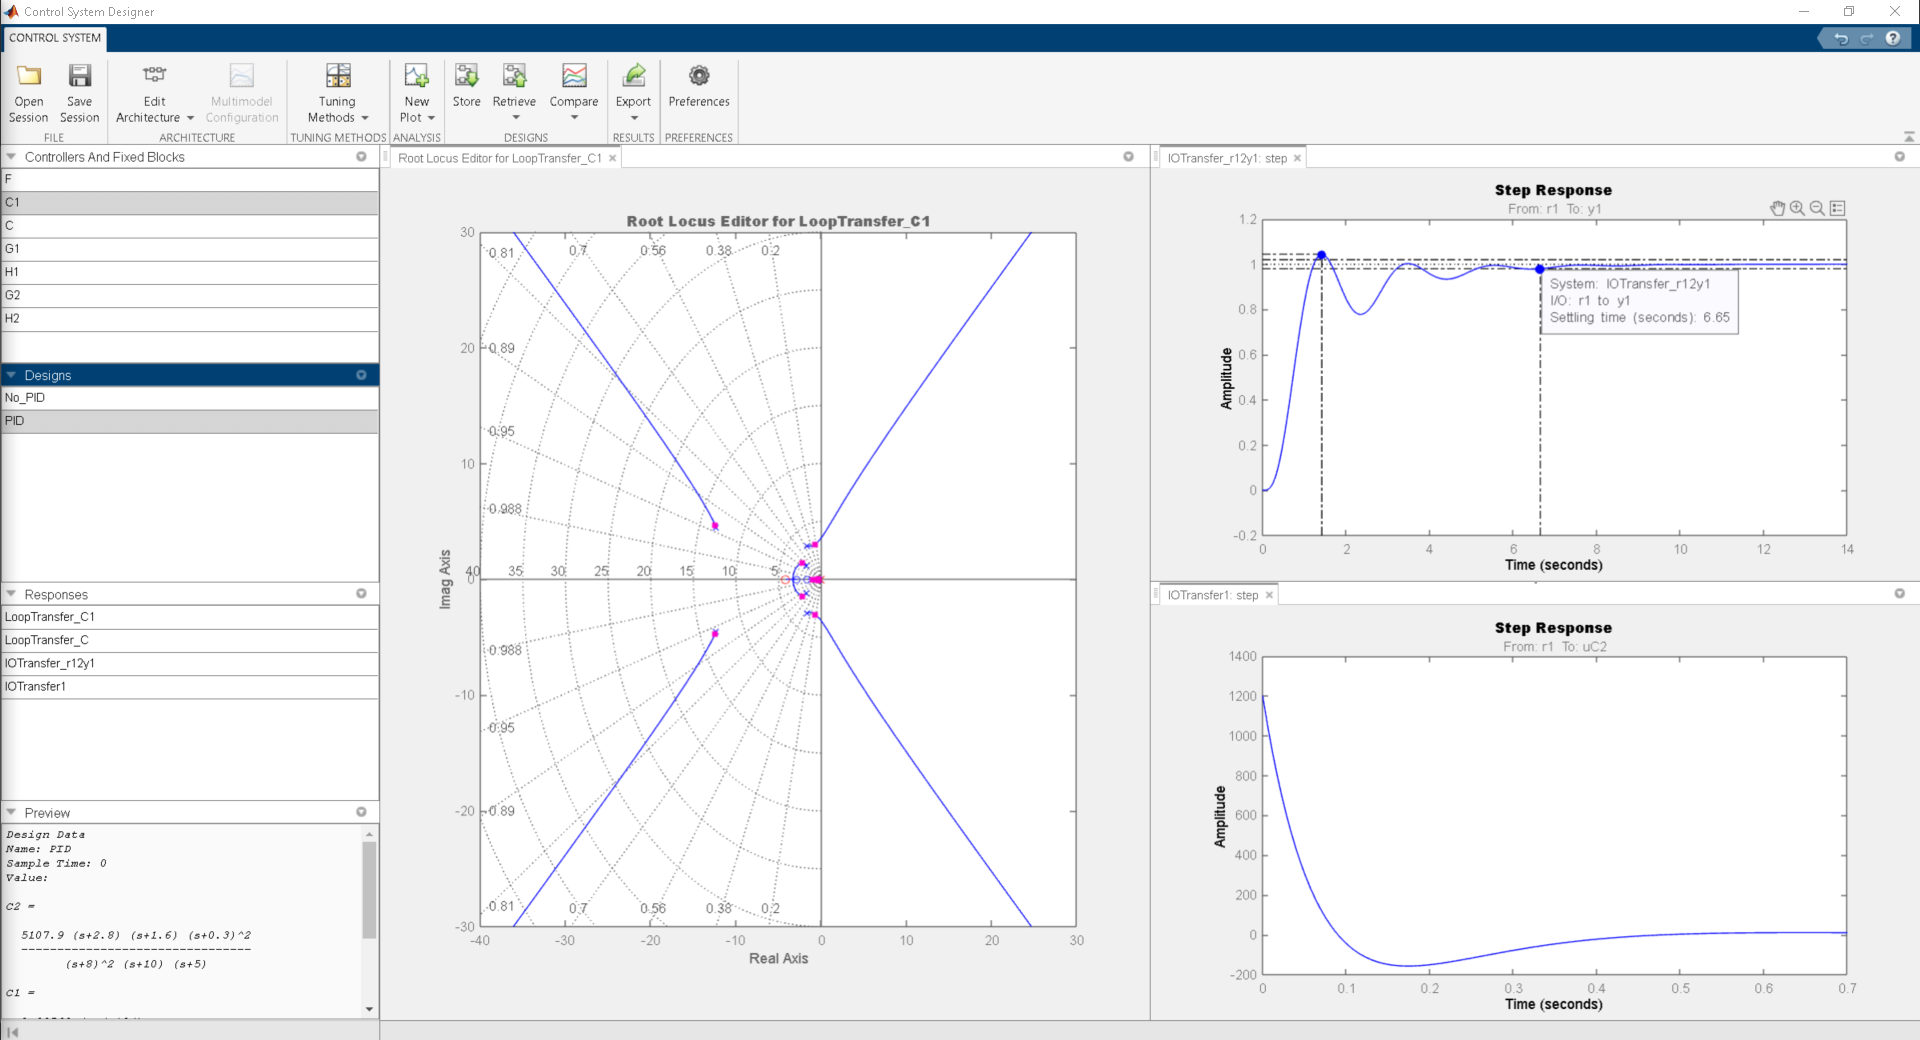

Unfortunately, while the PID can give us the desired peak response and settling time, the control signal is excessive and will cause problems with saturation, as seen in the model below:

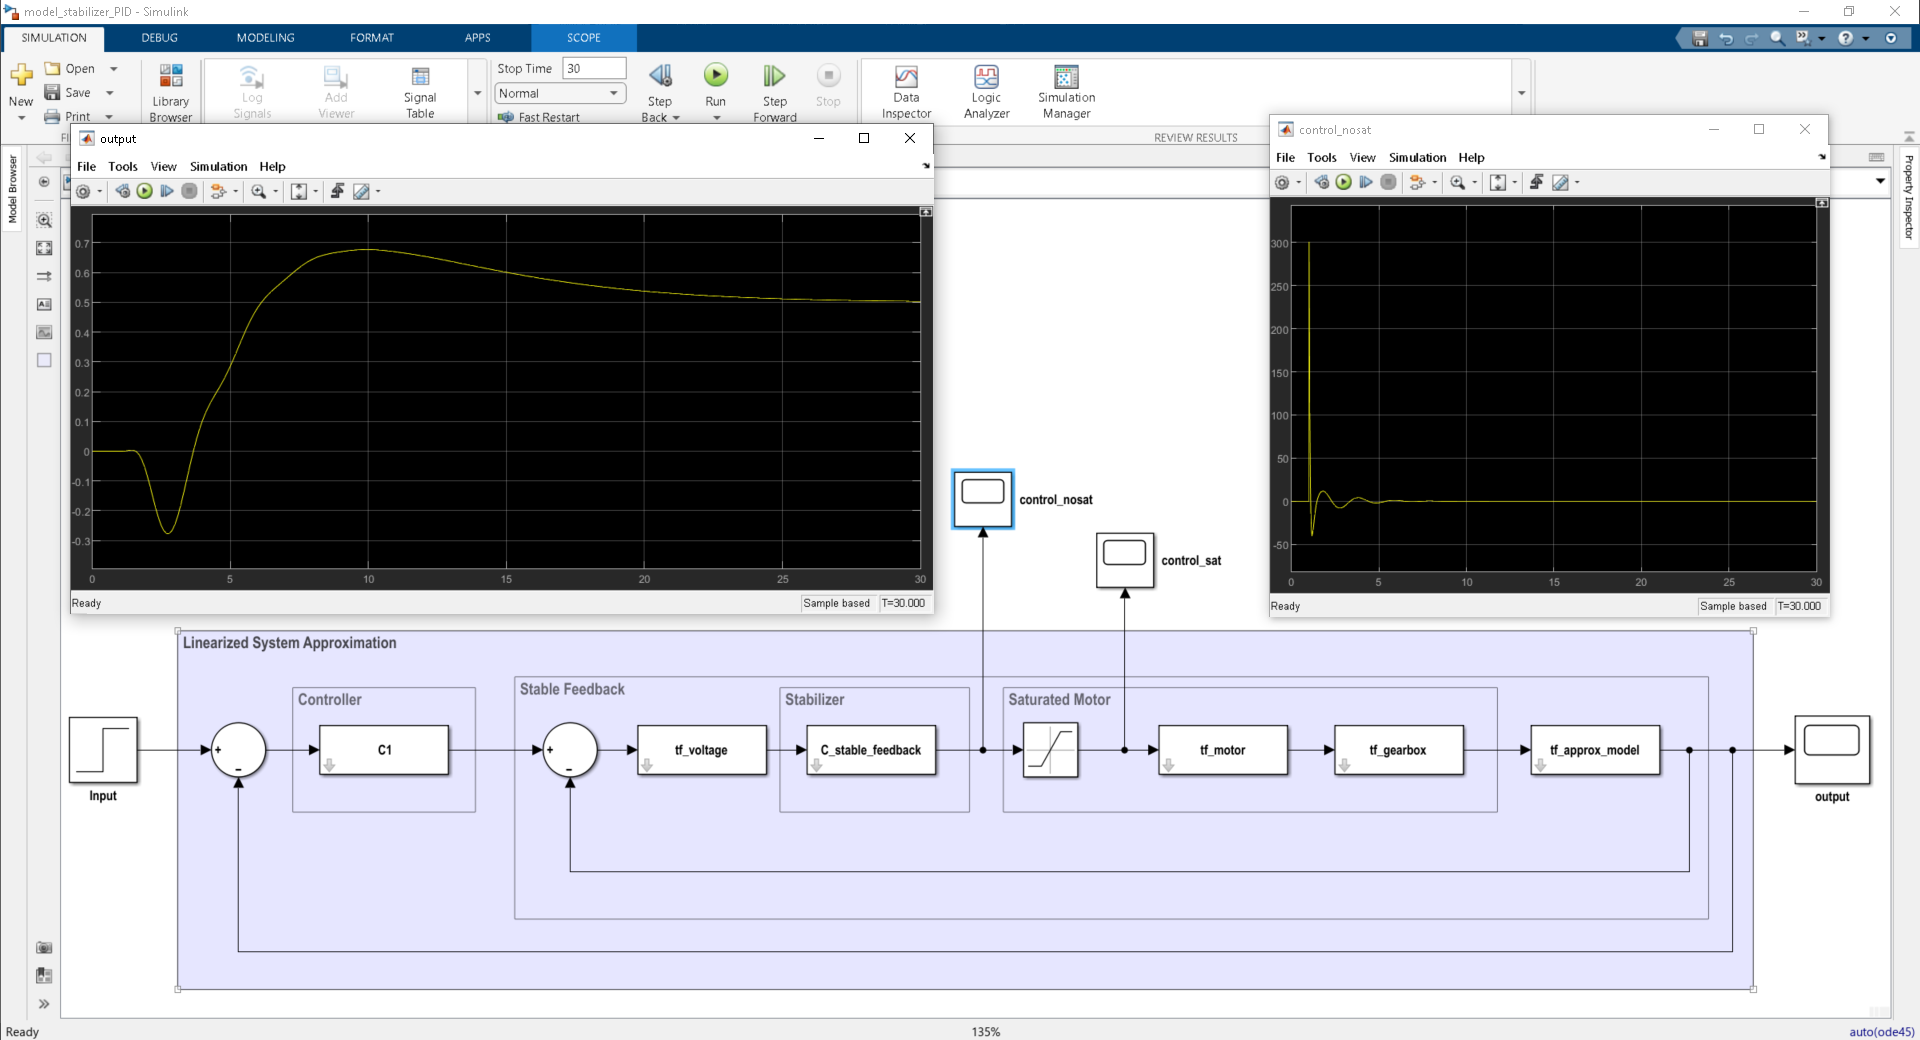

This model clearly shows the saturation causes negative effects on both the response time and peak response. To remedy this, we add a lag compensator to our PID controller. Check the `PID_design.mat` file to see the final controller. The controller value is imported:

load PID_design.mat
[~,~,temp] = ControlSystemDesignerSession.DesignerData.Designs.Data;
C_linearized_system = temp.C1;
clear temp

Which yields the following results for the saturated system (see `model_stabilizer_PID.slx`):

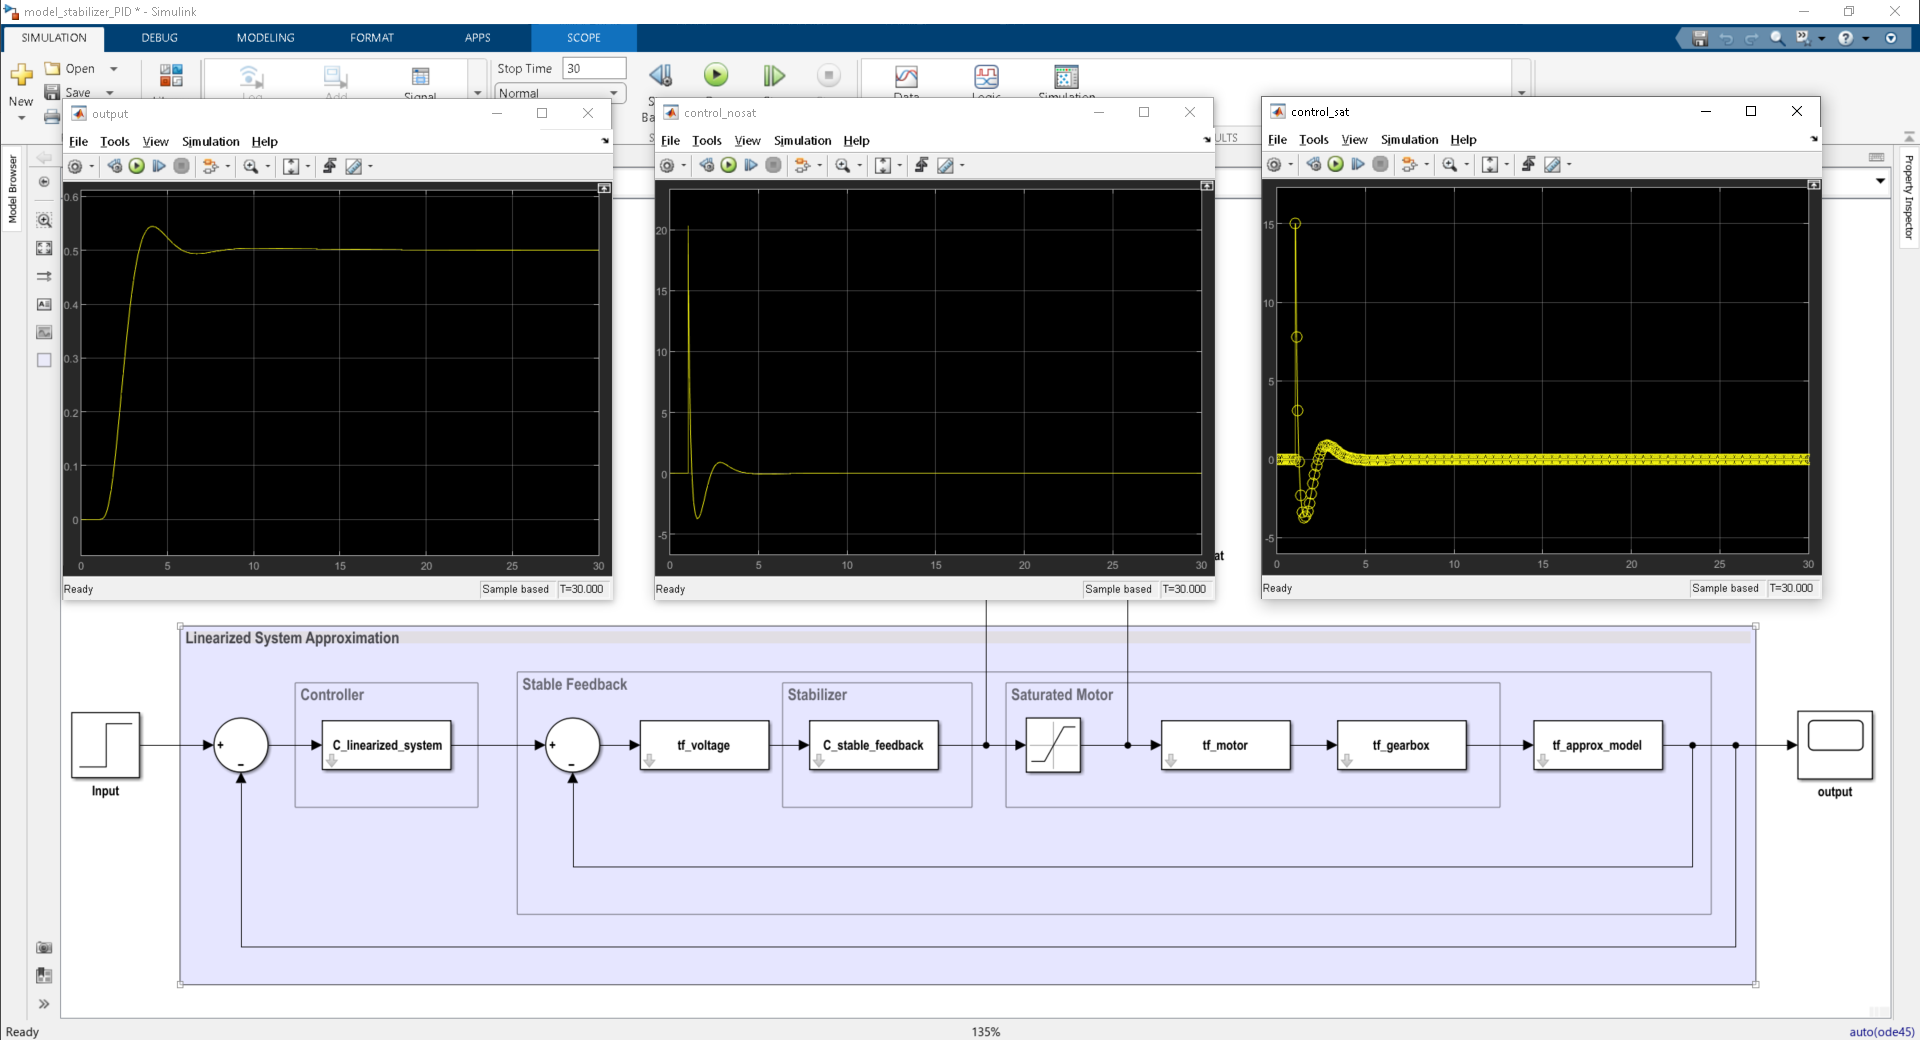

Which fulfils all the requirements.

Finally, the results for the real system are also plotted for this final design (see `model_stabilizer_PID_real.slx`):

 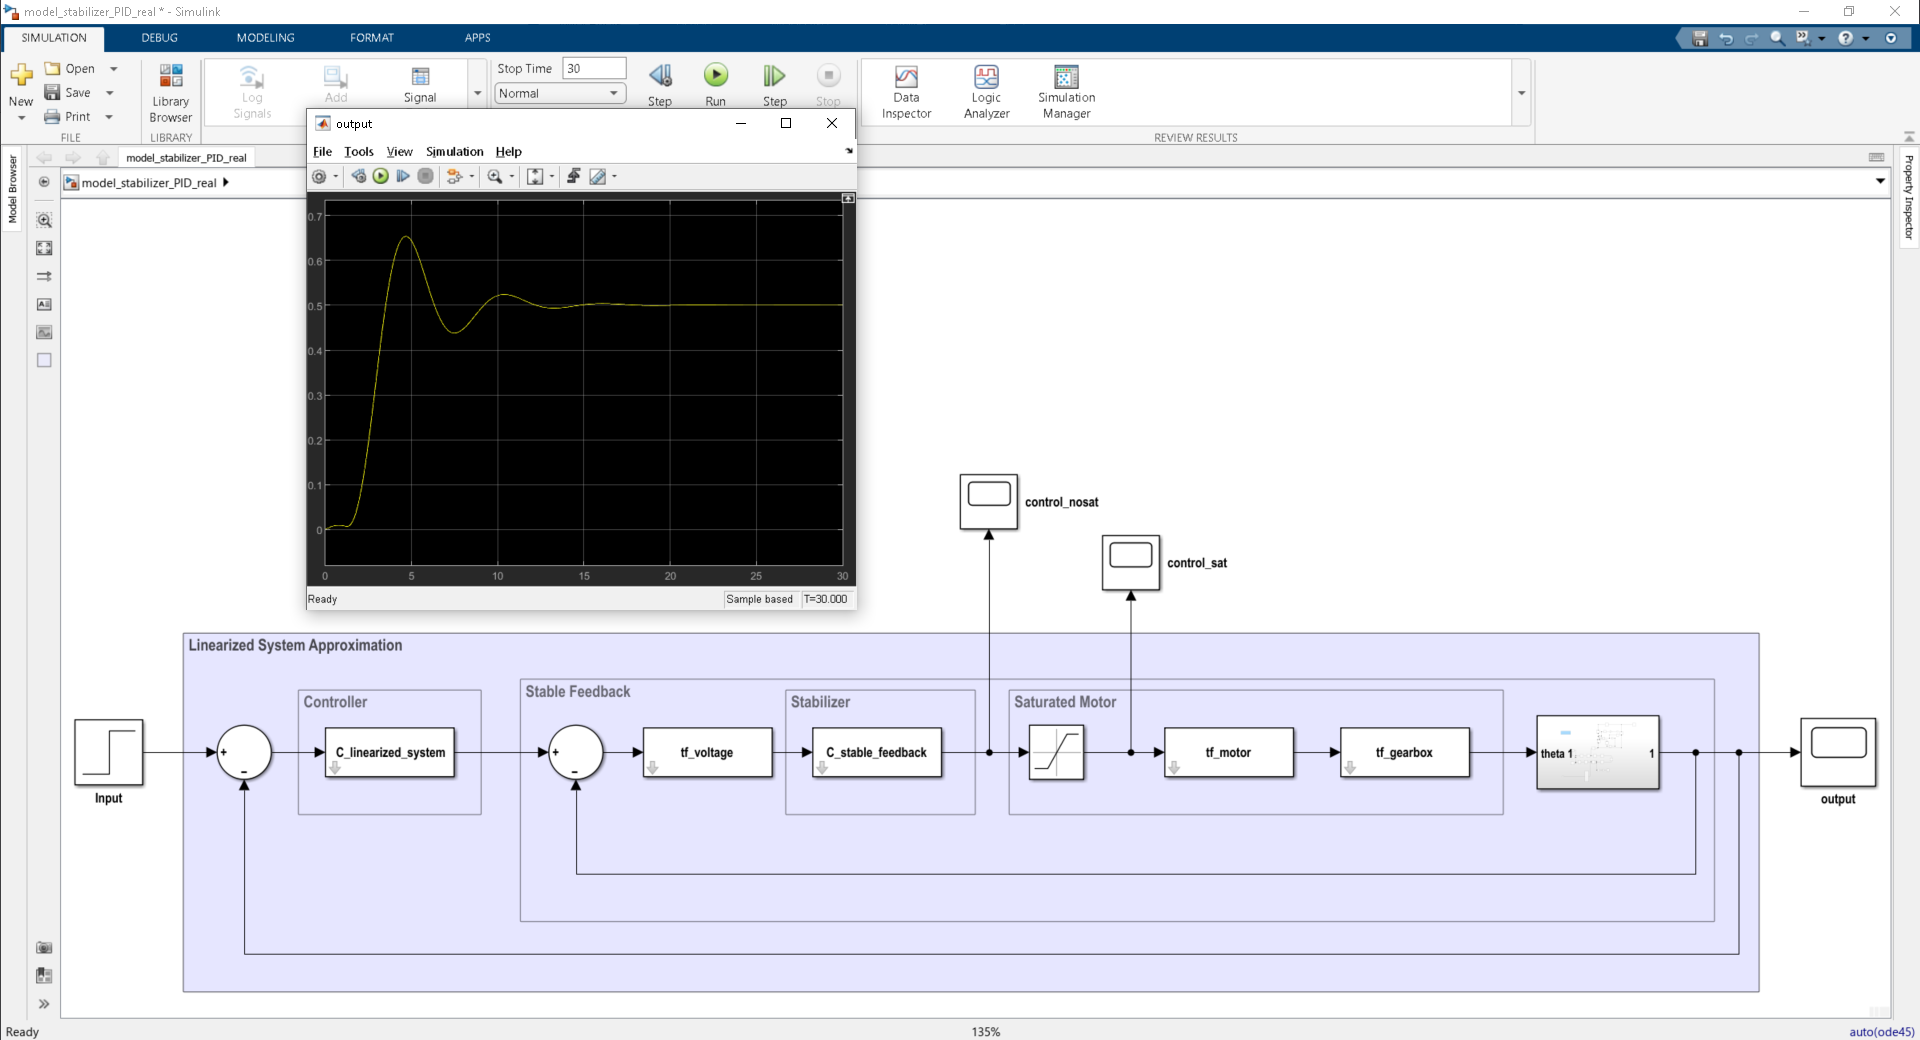

It is still stable, but overshoot and settling time are not the values we want. This is expected because the calculations were made for a simplified model of the problem.

## Designing a PID using the MATLAB PID-Tuner

In this part, to decouple the PID from the lag we designed in the previous section, we seperate these two from the controller transfer function:

tf_PID_lag = tf([1 -C_linearized_system.Z{1}(2)], [1 -C_linearized_system.P{1}(2)]);

The model for this system is saved in `model_stabilizer_PID_tuner.slx`. The PID is tuned using MATLAB's PID tuner.

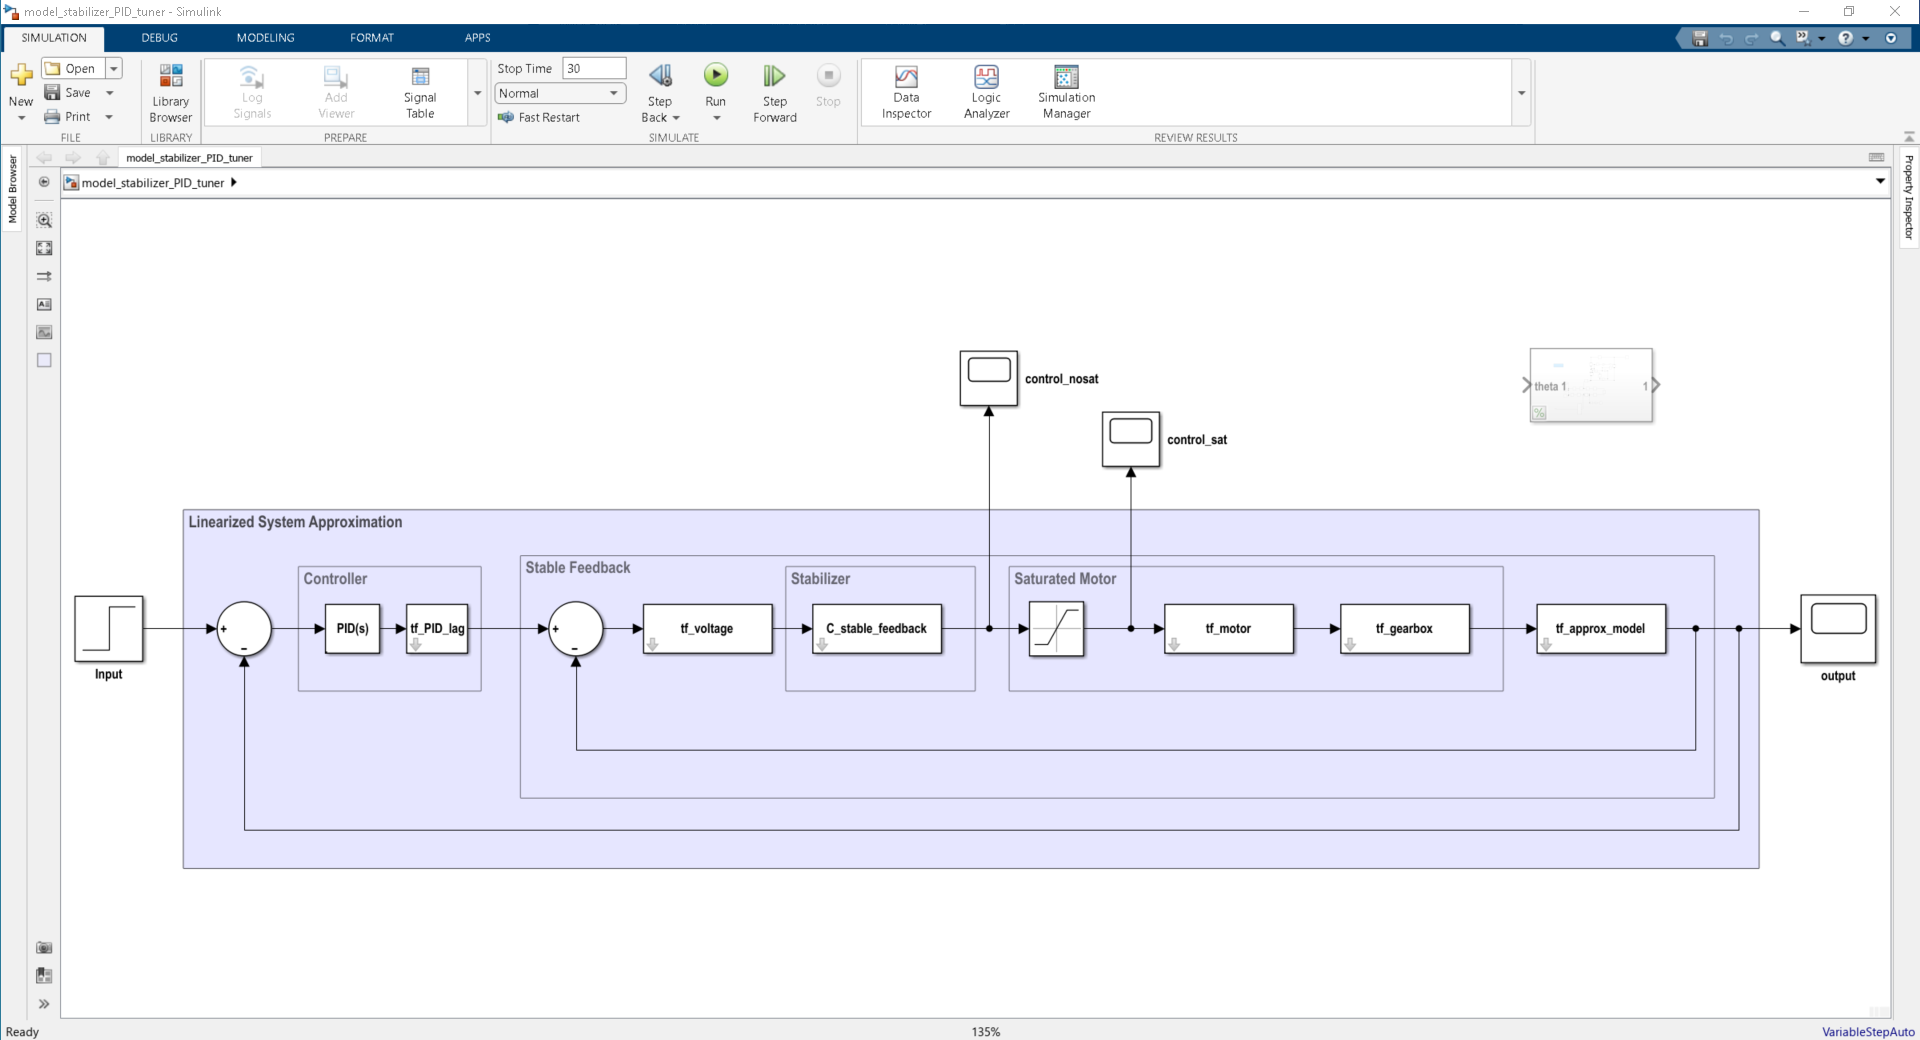

The results are even better with this method:

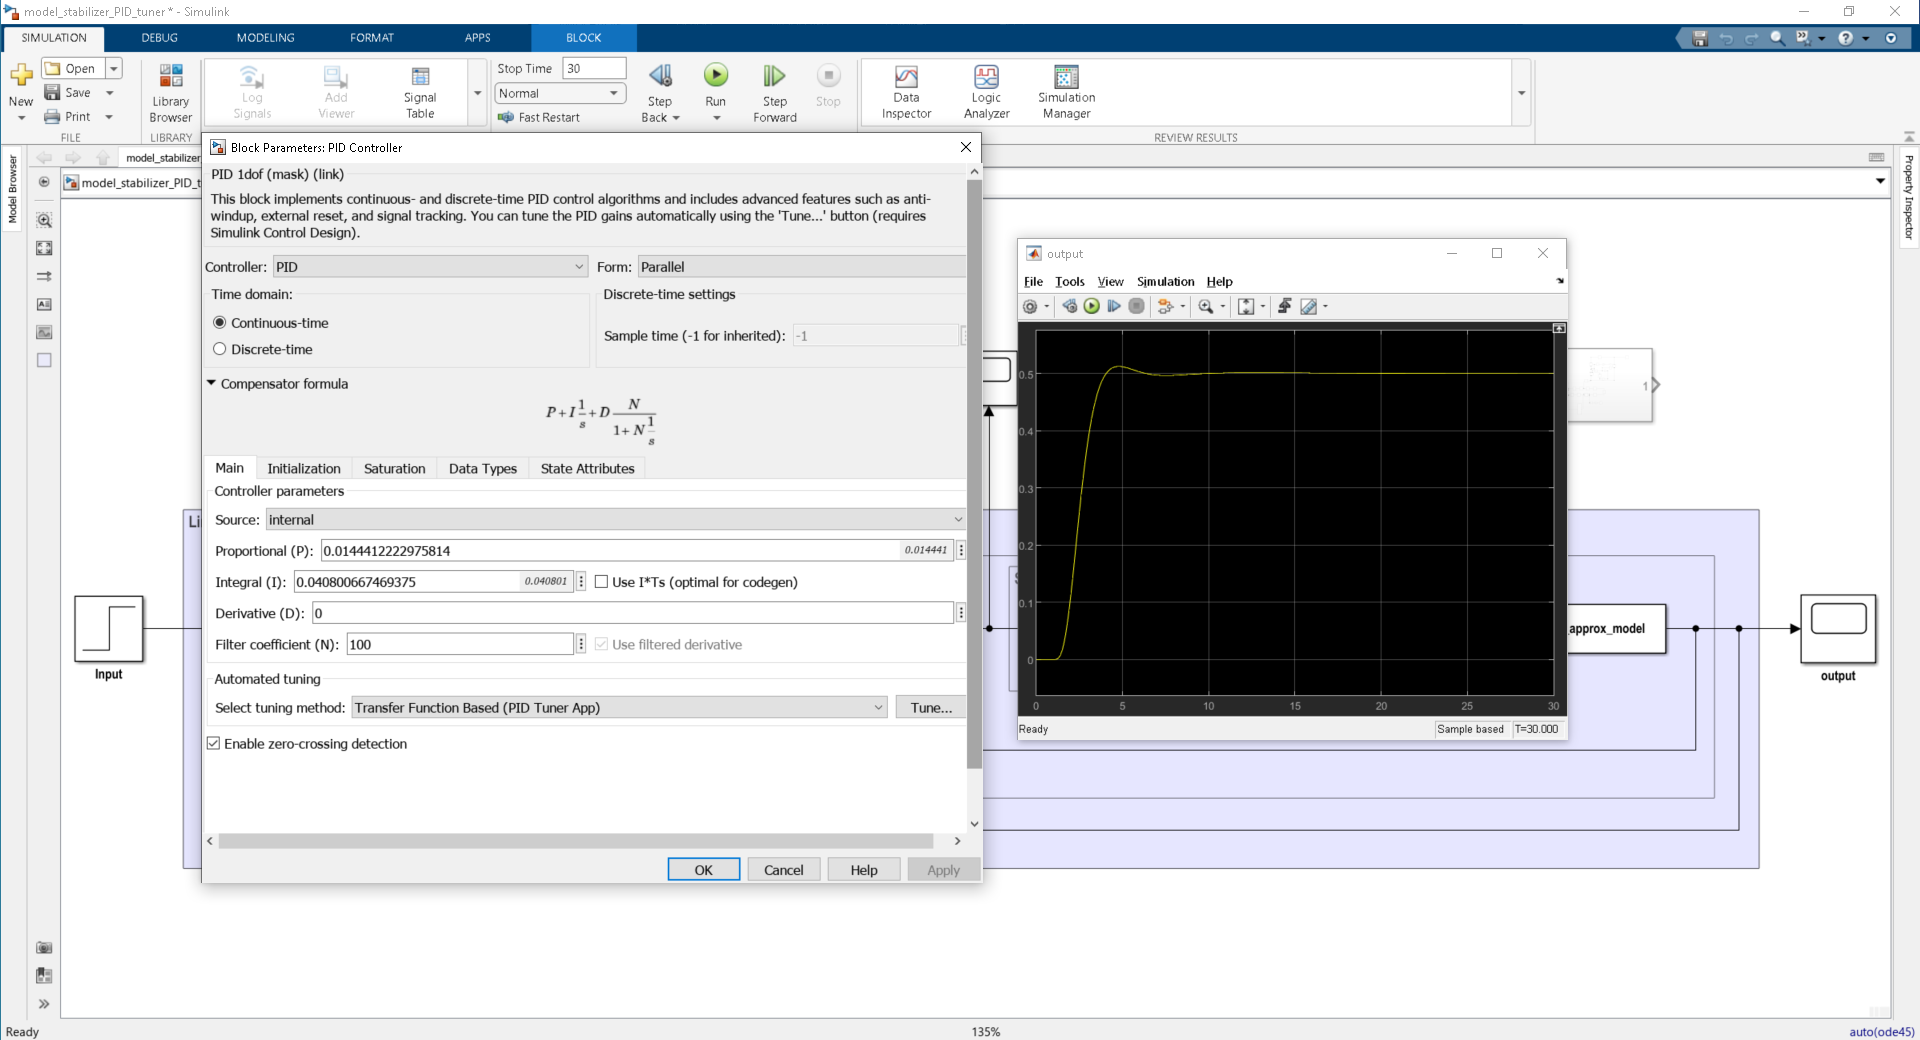

And for the real system (`model_stabilizer_PID_tuner_real.slx):`

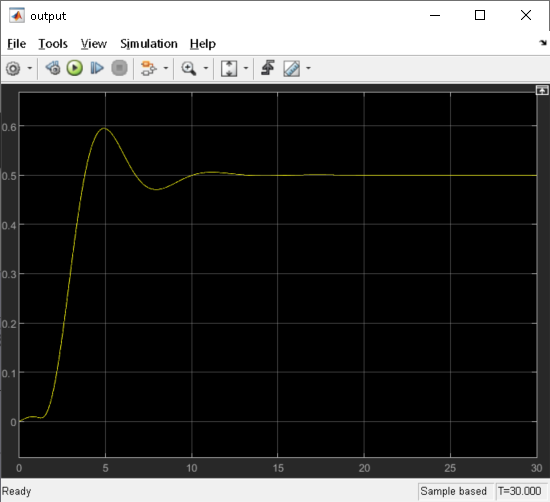

Which is closer to our goals.

## Using PID Designer Functions

Adding auxiliary functions to workspace.

addpath("auxiliary codes\", '-end');

For this section, controllers are designed for the unsaturated and approximated transfer function, and the best result is then used in the saturated and real model.

Now we compare the fod and opt approximations to choose which to use:

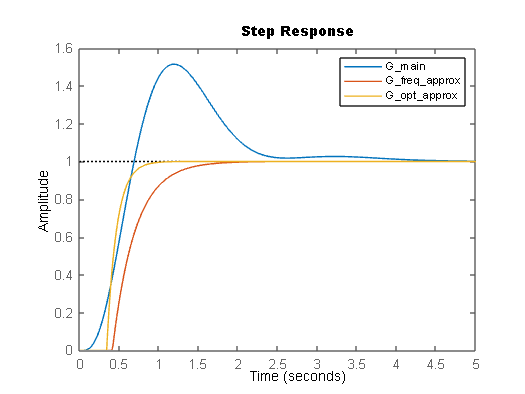

G_main = feedback(G_stable_feedback * C_stable_feedback, 1);
[K, L, T] = get_fod(G_main); % frequency method
G_freq_approx = K / (T * s + 1) * exp(-L * s);
G_opt_approx = opt_app(G_main, 0, 1, 1); % order of numerator: 0, denominator: 1, with delay
step(G_main, G_freq_approx, G_opt_approx);
legend();

None are a good approximation, but for the sake of solving the problem, the opt_approximation is chosen. K, L, T and other important values are extracted first.

L = G_opt_approx.IODelay;
K = G_opt_approx.Numerator{1}(2)/G_opt_approx.Denominator{1}(2);
T = 1/G_opt_approx.Denominator{1}(2);
[K_c, ~, wg, ~] = margin(G_main);
T_c = 2 * pi / wg;
K_p = dcgain(G_main);
N = 10; % assume

Now all the functions are used to find the best controller for this system.

### ZN method

[G_controller_ZN, ~, ~, ~, ~] = ziegler_nic(3, [K L T N]);
G_closedLoop_ZN = feedback(G_controller_ZN * G_main, 1);

### Refined ZN method

[G_controller_RZN, ~, ~, ~, ~, ~] = rziegler_nic([K L T N K_c T_c]);
G_closedLoop_RZN = feedback(G_controller_RZN * G_main, 1);

### Modified ZN method

The Modified ZN method requires manual tuning for the two values of `pb` and `rb`:

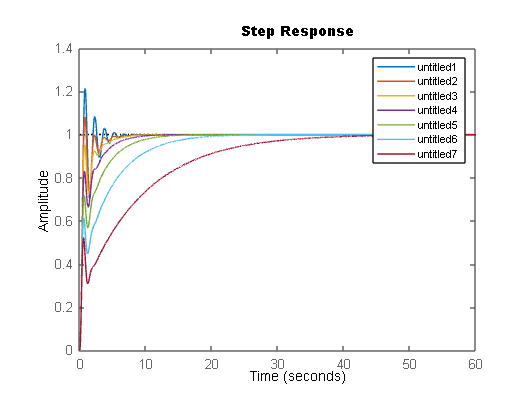

clf;
rb = 0.5;
hold on;
for pb=10:10:70
    [G_temp_controller_MZN, ~, ~, ~] = ziegler_nic(3, [K_c T_c rb pb 10]);
    step(feedback(G_temp_controller_MZN * G_main, 1));
end
hold off;
legend();

The value `pb`=20 is used. Now for `rb:`

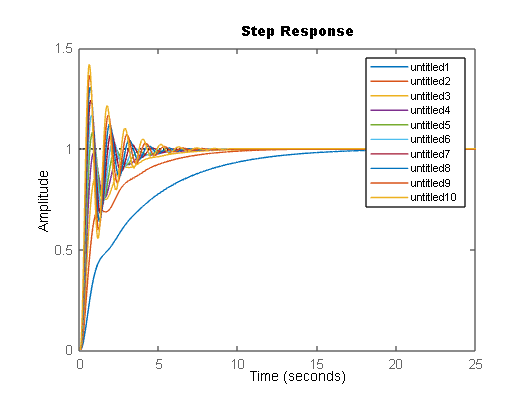

clf;
% modified ZN method
pb = 20;
hold on;
for rb=0.1:0.1:1
    [G_temp_controller_MZN, ~, ~, ~] = ziegler_nic(3, [K_c T_c rb pb 10]);
    step(feedback(G_temp_controller_MZN * G_main, 1));
end
hold off;
legend();

The value of `rb`=0.6 is used. Therefore

rb = 0.6;
[G_controller_MZN, ~, ~, ~] = ziegler_nic(3, [K_c T_c rb pb 10]);
G_closedLoop_MZN = feedback(G_controller_MZN * G_main, 1);

### CC method

[G_controller_CC,~,~,~,~] = cohen_pid(3, [K L T N], 0);
G_closedLoop_CC=feedback(G_controller_CC * G_main, 1);

### Revisited CC method

[G_controller_RCC,~,~,~,~] = cohen_pid(3, [K L T N], 0);
G_closedLoop_RCC=feedback(G_controller_RCC * G_main, 1);

### AH-S method

[G_controller_AH_S,~,~,~,~] = AH_pid(2, [K L T N], 0);
G_closedLoop_AH_S=feedback(G_controller_AH_S * G_main, 1);

### AH-F method

[G_controller_AH_F,~,~,~,~] = AH_pid(2, [K_c T_c K_p N], 1);
G_closedLoop_AH_F=feedback(G_controller_AH_F * G_main, 1);

### CHR method (set point following, 20% overshoot)

[G_controller_CHR_20pct,~,~,~,~] = chr_pid(1, 2, [K L T N, 20]);
G_closedLoop_CHR_20pct=feedback(G_controller_CHR_20pct * G_main, 1);

### WJC method

[G_controller_WJC,~,~,~] = wjcpid([K,L,T,N]);
G_closedLoop_WJC = feedback(G_controller_WJC * G_main, 1);

### Optimum PID (set point following, ISTE, PID/PI-D)

[G_controller_OPT_PID,~,~,~,~]=opt_pid(3,1,[K L T N 2]);
G_closedLoop_OPT_PID = feedback(G_controller_OPT_PID * G_main, 1);

[G_controller_OPT_PI_D,~,~,~,~]=opt_pid(4,1,[K L T N 2]);
G_closedLoop_OPT_PI_D = feedback(G_controller_OPT_PI_D * G_main, 1);

### Final remarks

Finally, all desings are plotted and compared.

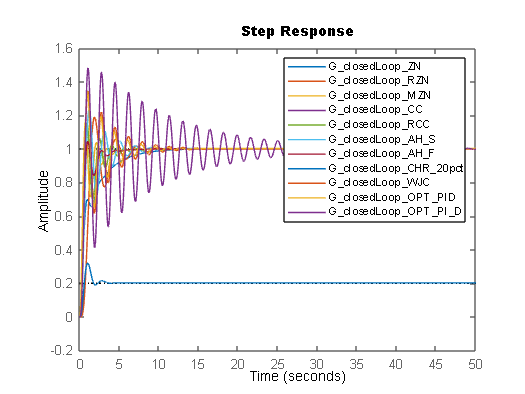

clf;
step(G_closedLoop_ZN, G_closedLoop_RZN, G_closedLoop_MZN, ...
    G_closedLoop_CC, G_closedLoop_RCC, G_closedLoop_AH_S, ...
    G_closedLoop_AH_F, G_closedLoop_CHR_20pct, ...
    G_closedLoop_WJC, G_closedLoop_OPT_PID, G_closedLoop_OPT_PI_D);
legend();

The controller chosen is `G_controller_MZN` since it has the least error and overshoot. The closed loop saturated system seen in the file `model_stabilizer_PID_functions.slx` shows the system is stable; however the settling time is too high due to the saturation:

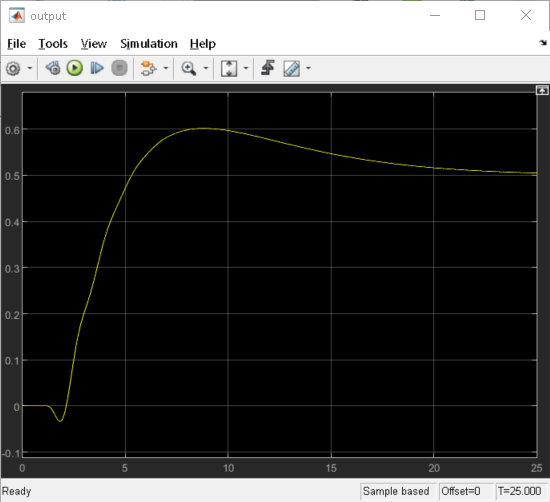

To fix this, a lead/lag compensator similar to the previous problem needs to be added. This is manually tuned to provide the desired outcome:

tf_PID_lag_functions = tf([1 4.5], [1 18.1]);

The resulting output will be valid:

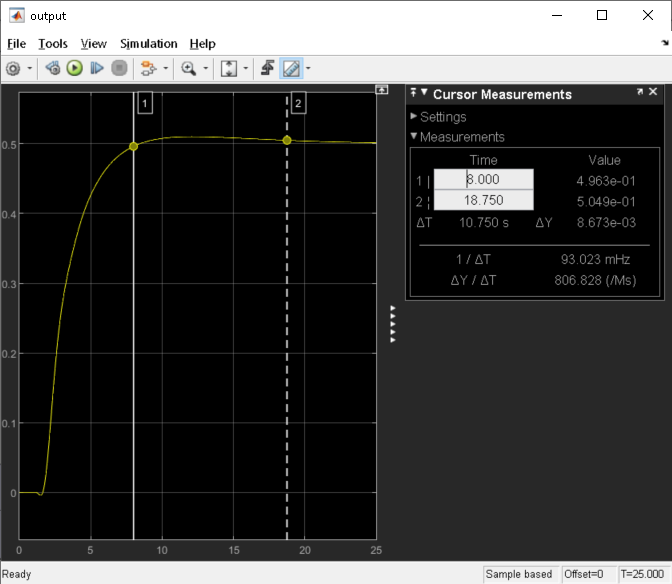

And when the real system is used (`model_stabilizer_PID_functions_real.slx), the following output appears:`

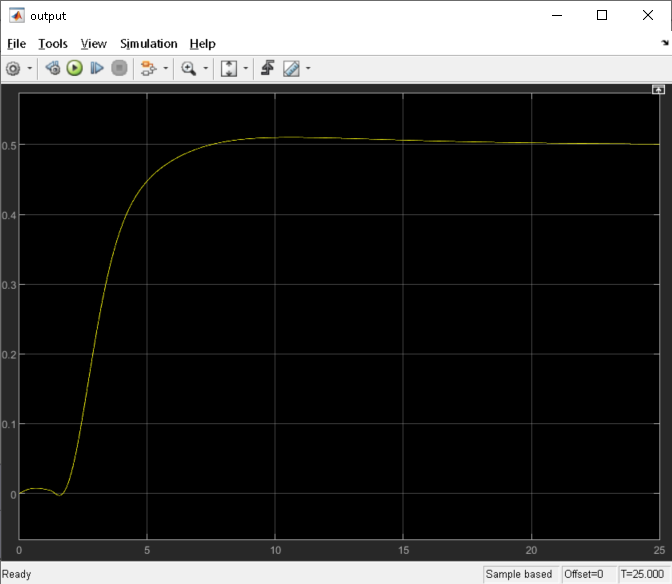

Which is the best result so far.

## Using the Optim PID tool

The Optim PID tool generates the following (ISTE method):

tf_controller_OPTIM_PID = 0.196 + 0.345/s + 0.0372*s;

The `model_stabilizer_PID_optim.slx` file shows  the full system with the real model. The filter coefficient is assumed to be **10**. The resulting output is as follows:

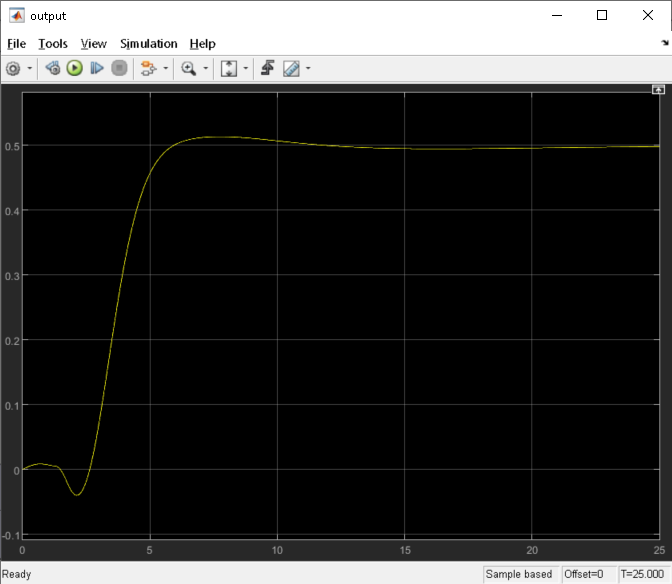

Which is one of the better results; since it doesn't even need a lead/lag compensator.

## 2-DOF PID Controller

Using the PID Tuner tool in our Simulink model (`model_stabilizer_PID_2DOF_real.slx), and with some fine tuning, the following output for the system is composed:`

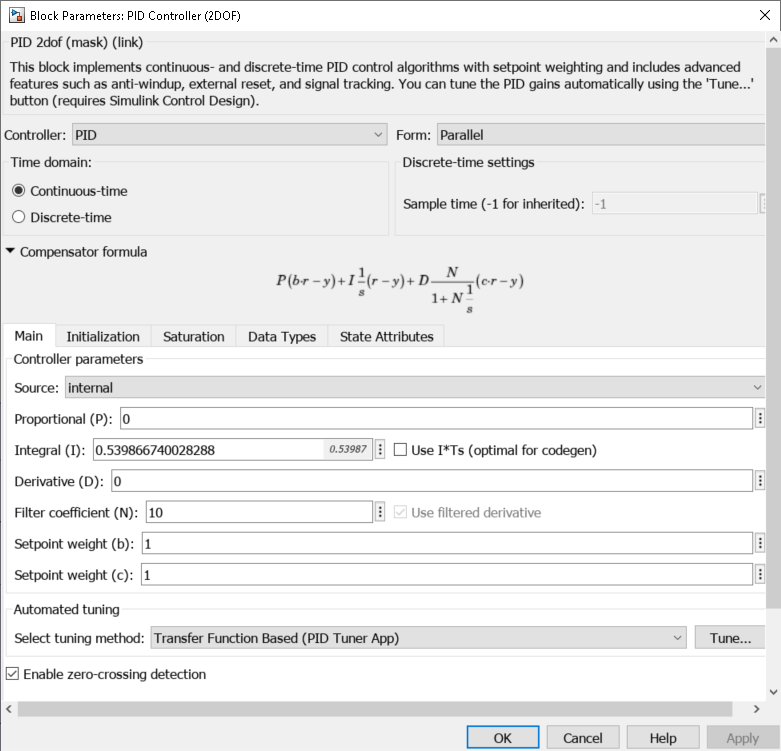

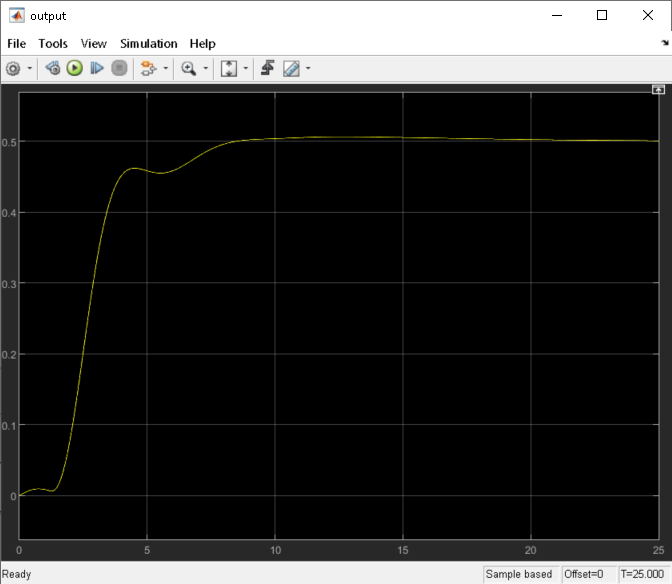

This is also acceptable for the system.

## Introducing Input Disturbance

In this section, only the response to the real system is considered, since taking into account the linearized system would have a small benefit at this point (the controllers have already been designed).

The disturbance is inserted right before the Saturated Motor block. Here is an example of disturbance added to the 2DOF PID example:

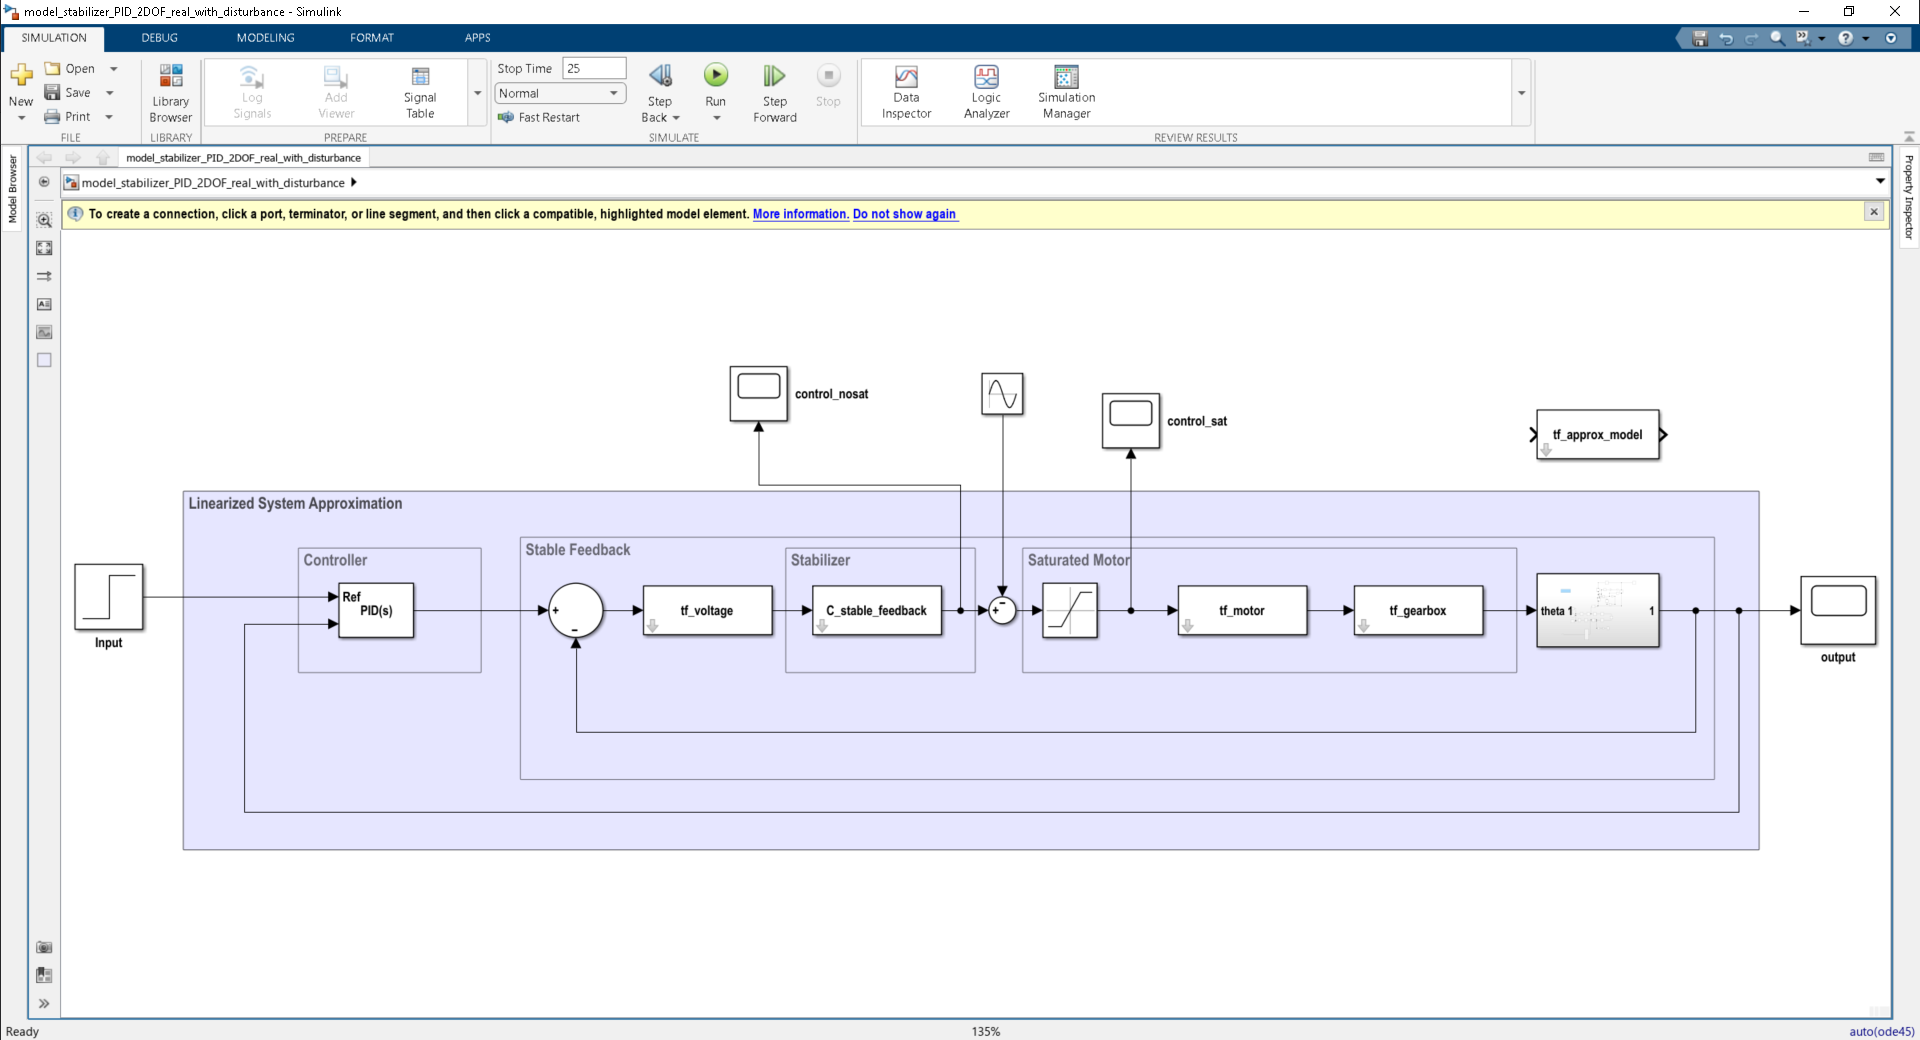

The disturbance block is assumed to have an amplitude of 1, and the frequency is given as **40Hz**.

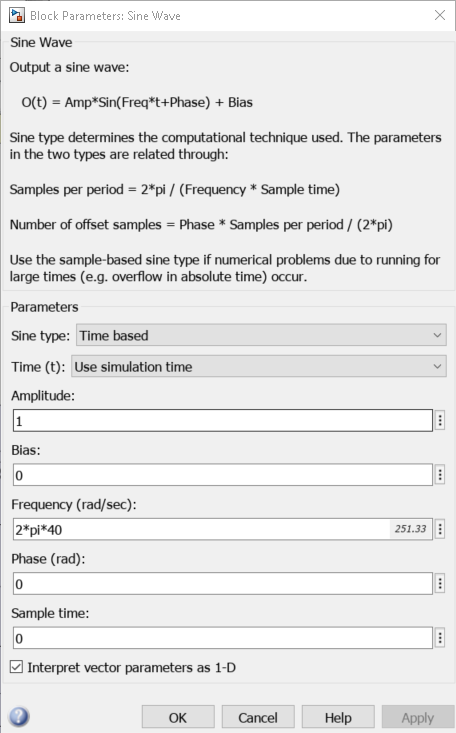

For this model, as seen in `model_stabilizer_PID_2DOF_real_with_disturbance.slx`, the disturbance actually doesn't affect the output too much, As seen below:

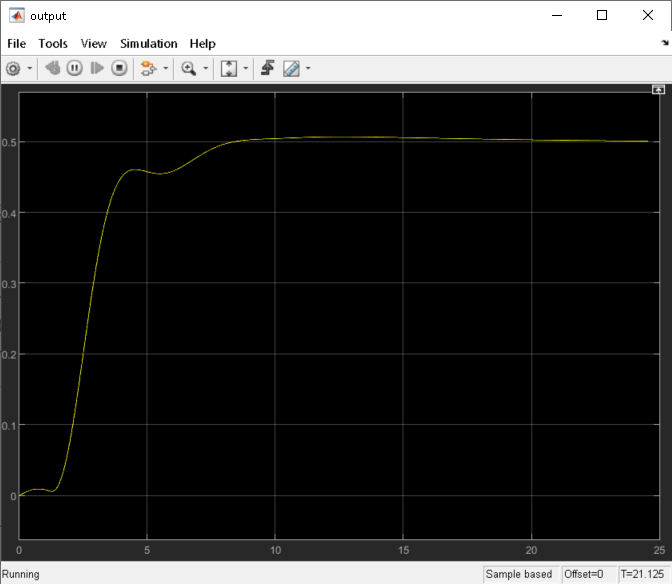

The effect of disturbance on the Optim PID design is also investigated; since it also yielded desirable results in the previous sections. In this model, however, disturbance causes a very slight increase of settling time over the desired 8 seconds. The system still remains stable though.

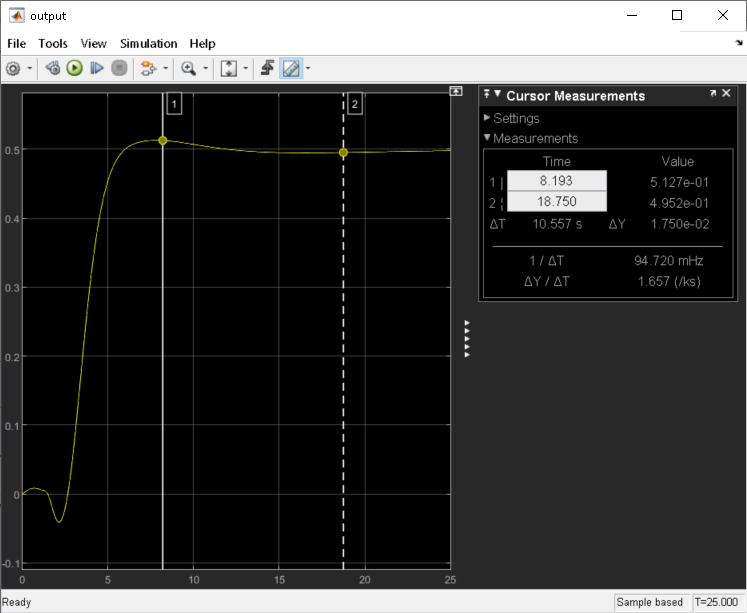

Overall, most of the designs are likely to be resistent to input disturbance, as the stabilizing controller likely deals with it. There might be slight alterations to settling time and overshoot though, which can be remedied by using simple lead/lag compensators as done previously. 